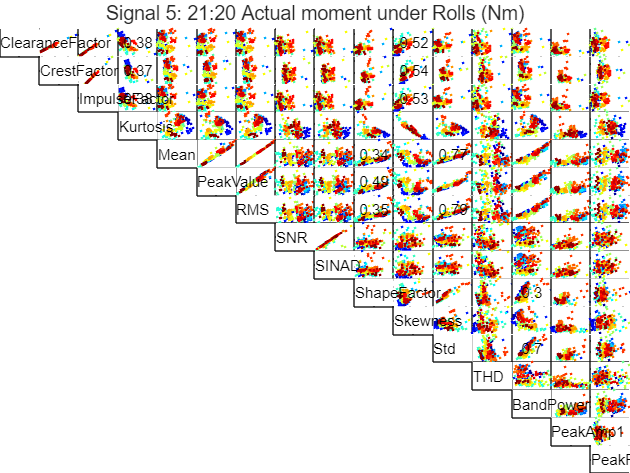

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
selectedSignal = 5;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  0.98  1.00  0.38  0.02  0.01  0.02  0.03  0.01  0.25  0.52  0.04  0.05  0.02  0.00  0.00
0.00  0.00  0.99  0.37  0.05  0.00  0.05  0.03  0.00  0.15  0.54  0.01  0.05  0.05  0.01  0.00
0.00  0.00  0.00  0.38  0.03  0.00  0.03  0.03  0.00  0.21  0.53  0.03  0.05  0.03  0.00  0.00
0.00  0.00  0.00  0.00  0.17  0.07  0.16  0.06  0.02  0.12  0.91  0.00  0.06  0.16  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.95  1.00  0.01  0.00  0.34  0.28  0.77  0.05  0.90  0.13  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.95  0.00  0.00  0.49  0.13  0.87  0.03  0.85  0.13  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.00  0.35  0.27  0.79  0.05  0.90  0.14  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.87  0.02  0.05  0.00  0.02  0.01  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.01  0.00  0.11  0.00  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.06  0.80  0.01  0.30  0.17  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2);
disp(selectedFeatureArray);

     1     4    11



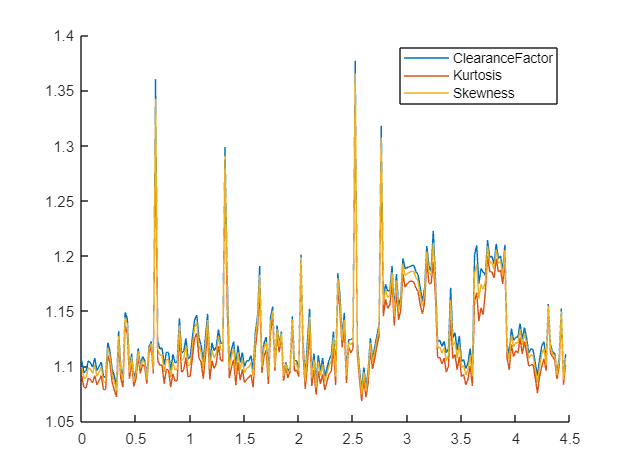

n = size(selectedFeatureData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for signalIndex = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{signalIndex});
    txtTemp = char(FeatureNames(selectedFeatureArray(signalIndex)));
    leg{signalIndex} = char(txtTemp);
end
title(sensorNames(selectedSignal));;
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

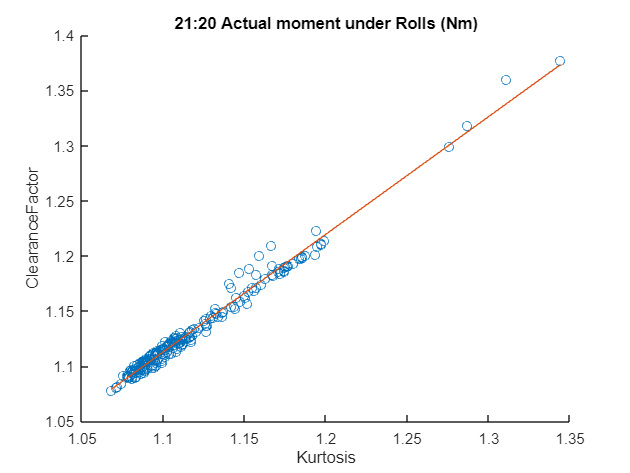

FIT = 87.21

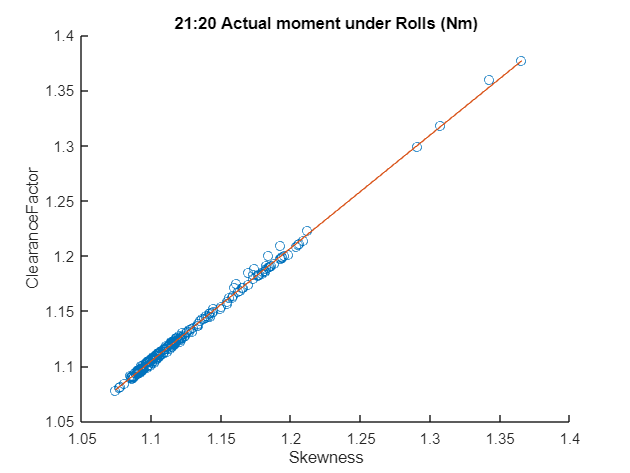

FIT = 94.95

for index = 1 : numOfSelectedFeatures
    if index ~= selectedFeature
        fnPlotModel(selectedFeatureData{selectedFeature}, selectedFeatureData{index}, sensorNames(selectedSignal), FeatureNames_Combined(selectedFeatureArray(selectedFeature)), FeatureNames_Combined(selectedFeatureArray(index)));
    end
end

1 2 3

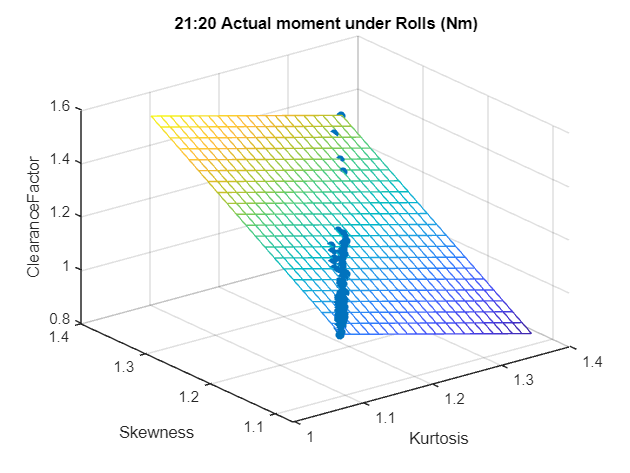

FIT = 99.403682

numOfSelectedFeatures = size(selectedFeatureArray,2);
for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end